In this example we will consider a stable system. We will attempt to improve this systems stability by finding a controller $K$ which inproves the preformence with respect to the $\mathcal{H}_2$ norm. This method will be applicable for both stable and stabilised systems, since in a lot of cases it is easier to find a controller when we disregard the preformance constraints. We will also compare how much data we need to find a stabilising $\mathcal{H}_2$ controller directly from the data compared by finding a stabilising controller beforehand. In practice there might already be a controller in place for a process that we want to improve. For this we can add the controller to the process. I.e. $A + B K + B K_{improved} = A + B (K + K_{improved})$. 

## Defining stable system

In the first part of this example will consider the following stable descrete time system using random noice picked from a uniform distribution from $[-\epsilon , \epsilon]$. We will generate $T$ samples.

% System matrices
A = [0.5 0 0 ; 0 0.9 0 ; 0 0 0.1];
B = [1 0 ; 1 0 ; 0 1];
epsilon = 0.01;
T = 500;
[n,m] = size(B);

% Noice matrix
Phi_11 = @(T) epsilon^2 * T * ones(n,n);  % Worst case noise bound, best case : W * W'
Phi_12 = @(T) zeros(n,T);
Phi_22 = @(T) -eye(T);
f_Phi = @(T) [Phi_11(T) Phi_12(T) ; Phi_12(T)' Phi_22(T)];

% Input, initial condition and noise generating functions
f_x0 = @() 2 * rand([n 1]) - 1;
f_U  = @(batchSize) 0.2  * (2 * rand([m batchSize]) - 1);
f_W  = @(batchSize) epsilon * (2 * rand([n batchSize]) - 1);

% Preformance output matrices
C = [1 1 0];
D = [0 0];
[p,~] = size(C);

gamma = @(A,B,K) trace(dlyap((A+B*K)',(C+D*K)'*C+D*K));
% Finding the optimal preformance of the closed loop system
tol = 10^(-6);
options = sdpsettings('solver','mosek','debug',1,'verbose',0);
options.mosek.MSK_DPAR_SEMIDEFINITE_TOL_APPROX = 10^(-15);

## Improving preformance of the closed loop system using H2

Now that we have our data from a stable sytem, we will define our preformance output matrices $C$ and $D$. We will use them to find the preformance of the current system.

% Finding the preformance of the system with K = 0
K = zeros(m,n);
gamma_0 = gamma(A,B,K);
fprintf('performance without a controller: %d \n', gamma_0);

performance without a controller: 6.596491e+00 



Y = sdpvar(n,n);
Z = sdpvar(p,p);
L = sdpvar(m,n);
gamma2 = sdpvar(1,1);
LMI = [Y >= tol, ...
       gamma2 >= 0, ...
       [Y (A*Y+B*L)' (C*Y+D*L)';(A*Y+B*L) Y zeros(n,p);(C*Y+D*L) zeros(p,n) eye(p)] >= tol, ...
       [Z [1 1 1];[1 1 1]' Y] >= 0, ...
       trace(Z) <= gamma2];
optimize(LMI,gamma2,options);
gammabest = sqrt(value(gamma2))

gammabest = 2.0000

Kbest = value(L)/value(Y);

We will now attempt to increase the preformance of the closed loop system using the noisy data we generated from the system. To do this we will use the function `[bool, K] = isInformH2(X, U, Phi, C, D, tolerance, options)` provided by this toolbox.

plot(1:T, gamma_0 * ones(1,T))
hold on
title('performance \gamma of the controller found');
xlabel('number of data points used');
ylabel('\gamma');
ylim([1,8])
plot(1:T, gammabest * ones(1,T))
number_of_tests = 5;
step_size = 1;
gammas = zeros(number_of_tests,T);

parfor i = 1:number_of_tests
    x0 = f_x0();
    U  = f_U(T);
    W  = f_W(T);
    [U, X] = generateData(A, B, x0, U, [], [], W);
    for idx = 1:step_size:T
        [~, K] = isInformH2(X(:,1:idx+1), U(:,1:idx), feval(f_Phi,idx), C, D, tol, options);
        gammas(i,idx) = feval(gamma,A,B,K);
    end
    fprintf('Bulk thread %d finished.\n', i)
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Bulk thread 3 finished.
Bulk thread 1 finished.
Bulk thread 5 finished.
Bulk thread 2 finished.
Bulk thread 4 finished.


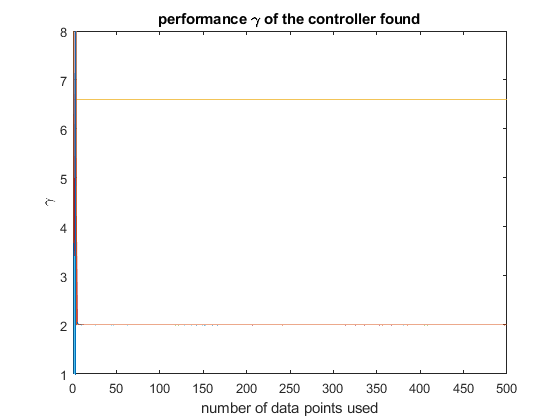

plot(1:T,gammas')
hold off

testing what happence if we repeat the process

A_i = A;
B_i = B;
K_i = zeros(m,n);
gamma_0 = gamma(A_i,B_i,K_i);
batchSize = 50;
iterations = 10;
gamma_i = zeros(number_of_tests, iterations * batchSize);
number_of_tests = 20;

plot(1:iterations*batchSize, gamma_0 * ones(1,iterations*batchSize))
hold on
title('performance \gamma of the controler found after each batch');
xlabel(sprintf('Number of batches of size %d', batchSize));
ylabel('\gamma');
ylim([1,7])
plot(1:iterations*batchSize, gammabest * ones(1,iterations*batchSize))


for i = 1:number_of_tests  % Number of independent simulations
    A_i = A;
    B_i = B;
    for iter = 1:iterations  % Number of times to update
        x0_i = f_x0();
        U_i  = f_U(batchSize);
        W_i  = f_W(batchSize);
        [U_i, X_i] = generateData(A_i, B_i, x0_i, U_i, [], [], W_i);
        for idx = 1:batchSize
            [~, K_i] = isInformH2(X_i(:,1:idx+1), U_i(:,1:idx), f_Phi(idx), C, D, tol, options);
            index = (iter-1) * batchSize + idx;
            gamma_i(i, index) = gamma(A_i,B_i,K_i);
        end
        A_i = A_i + B_i * K_i;
    end
    fprintf('Batch thread %d finished.\n', i)
end

Batch thread 1 finished.
Batch thread 2 finished.
Batch thread 3 finished.
Batch thread 4 finished.
Batch thread 5 finished.
Batch thread 6 finished.
Batch thread 7 finished.
Batch thread 8 finished.
Batch thread 9 finished.
Batch thread 10 finished.
Batch thread 11 finished.
Batch thread 12 finished.
Batch thread 13 finished.
Batch thread 14 finished.
Batch thread 15 finished.
Batch thread 16 finished.
Batch thread 17 finished.
Batch thread 18 finished.
Batch thread 19 finished.
Batch thread 20 finished.


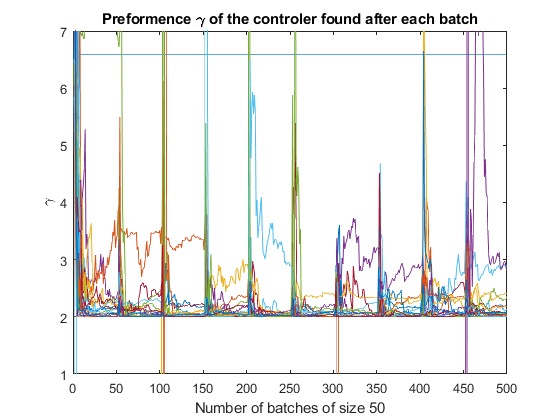

plot(gamma_i')

hold off